% run_phase4_feature_interpretation.m
%
% Script for Phase 4: Final Interpretation & Reporting.
% Focuses on identifying key discriminative wavenumbers from the final
% MRMRLDA model and their importance as indicated by LDA coefficients.
%
% Date: 2025-05-16

%% 0. Initialization
% =========================================================================
clear; clc; close all;
fprintf('PHASE 4: Feature Interpretation - %s\n', string(datetime('now')));

PHASE 4: Feature Interpretation - 16-May-2025 21:22:24



% --- Define Paths (Simplified) ---
projectRoot = pwd; % Assumes current working directory IS the project root.
if ~exist(fullfile(projectRoot, 'src'), 'dir') || ~exist(fullfile(projectRoot, 'data'), 'dir')
    error(['Project structure not found. Please ensure MATLAB''s "Current Folder" is set to your ' ...
           'main project root directory before running. Current directory is: %s'], projectRoot);
end

dataPath      = fullfile(projectRoot, 'data');
modelsPath    = fullfile(projectRoot, 'models', 'Phase3');
resultsPath   = fullfile(projectRoot, 'results', 'Phase4'); % Specific to Phase 4
figuresPath   = fullfile(projectRoot, 'figures', 'Phase4'); % Specific to Phase 4

if ~exist(resultsPath, 'dir'), mkdir(resultsPath); end
if ~exist(figuresPath, 'dir'), mkdir(figuresPath); end

dateStr = string(datetime('now','Format','yyyyMMdd'));

%% 1. Load Final Model Package from Phase 3
% =========================================================================
fprintf('Loading final model package from Phase 3...\n');

Loading final model package from Phase 3...


modelFiles = dir(fullfile(modelsPath, '*_Phase3_FinalMRMRLDA_Model.mat'));
if isempty(modelFiles)
    error('No Phase 3 final model file found in %s. Run Phase 3 script first.', modelsPath);
end
[~,idxSort] = sort([modelFiles.datenum],'descend');
latestModelFile = fullfile(modelsPath, modelFiles(idxSort(1)).name);
fprintf('Using final model from: %s\n', latestModelFile);

Using final model from: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\models\Phase3\20250515_Phase3_FinalMRMRLDA_Model.mat


try
    load(latestModelFile, 'finalModelPackage');
catch ME
    fprintf('ERROR loading final model package from %s: %s\n', latestModelFile, ME.message);
    return;
end

% Extract necessary components
finalLDAModel         = finalModelPackage.LDAModel;
selectedWavenumbers   = finalModelPackage.selectedWavenumbers; % These are the binned wavenumbers used by LDA
% selectedFeatureIndices = finalModelPackage.selectedFeatureIndices_in_binned_space; % Indices within the binned space
% binnedWavenumbersAll = finalModelPackage.binnedWavenumbers_for_selection; % All wavenumbers after binning

if isempty(selectedWavenumbers) || isempty(finalLDAModel.Coeffs)
    error('Selected wavenumbers or LDA coefficients not found in the loaded model package.');
end

fprintf('%d features (binned wavenumbers) were used by the final LDA model.\n', length(selectedWavenumbers));

50 features (binned wavenumbers) were used by the final LDA model.



% run_phase4_feature_interpretation.m
% ... (Section 0 and Section 1 remain the same - loading finalModelPackage, etc.) ...

%% 2. Extract and Analyze LDA Coefficients
% =========================================================================
fprintf('\n--- Analyzing LDA Coefficients ---\n');


--- Analyzing LDA Coefficients ---



finalLDAModel         = finalModelPackage.LDAModel;
selectedWavenumbers   = finalModelPackage.selectedWavenumbers; % Binned wavenumbers used by LDA
% Indices of selected features within the *binned* feature space
selectedFeatureIndices_in_binned = finalModelPackage.selectedFeatureIndices_in_binned_space; 

if isempty(selectedWavenumbers) || isempty(finalLDAModel.Coeffs)
    error('Selected wavenumbers or LDA coefficients not found in the loaded model package.');
end

classNames = finalLDAModel.ClassNames; 
fprintf('LDA Model Class Names: %s\n', mat2str(classNames));

LDA Model Class Names: [1;3]


idx_who3_in_model = find(classNames == 3);
idx_who1_in_model = find(classNames == 1);
if isempty(idx_who3_in_model) || isempty(idx_who1_in_model)
    error('Could not find both WHO-1 and WHO-3 in the LDA model class names.');
end

ldaCoefficients = [];
if idx_who3_in_model == 2 
    ldaCoefficients = finalLDAModel.Coeffs(1,2).Linear;
    fprintf('Interpreting positive LDA coefficients as indicative of WHO-3.\n');
elseif idx_who1_in_model == 2 
    ldaCoefficients = -finalLDAModel.Coeffs(1,2).Linear;
    fprintf('Interpreting NEGATIVE of Coeffs(1,2).Linear as indicative of WHO-3.\n');
else
    error('Unexpected class order or setup in LDA model coefficients.');
end

Interpreting positive LDA coefficients as indicative of WHO-3.



if length(ldaCoefficients) ~= length(selectedWavenumbers)
    error('Mismatch between number of LDA coefficients (%d) and number of selected features (%d).', ...
        length(ldaCoefficients), length(selectedWavenumbers));
end

directionInfluence = strings(length(ldaCoefficients), 1);
directionInfluence(ldaCoefficients > 0) = "Higher in WHO-3";
directionInfluence(ldaCoefficients < 0) = "Lower in WHO-3 (Higher in WHO-1)";
directionInfluence(ldaCoefficients == 0) = "No linear influence";

% Initial feature importance table (without p-values yet)
featureImportanceTable = table(...
    selectedWavenumbers(:), ... 
    ldaCoefficients(:), ...   
    directionInfluence, ...
    'VariableNames', {'BinnedWavenumber_cm_neg1', 'LDACoefficient', 'DirectionOfInfluence_WHO3'});

fprintf('%d features (binned wavenumbers) were used by the final LDA model.\n', ...
    length(selectedWavenumbers));

50 features (binned wavenumbers) were used by the final LDA model.




%% 2.5 Calculate Univariate P-values for Selected Features
% =========================================================================
fprintf('\n--- Calculating Univariate P-values for the %d Selected Features ---\n', length(selectedWavenumbers));


--- Calculating Univariate P-values for the 50 Selected Features ---



% Load the binned training data used to train the final model
% We need X_train_binned (corresponding to finalModelPackage.binningFactor)
% and y_train_full.
% X_train_binned was created in Phase 3 script, but not saved in finalModelPackage.
% So, we need to reload X_train_full and y_train_full and re-bin it.

fprintf('Reloading and binning full training data for p-value calculation...\n');

Reloading and binning full training data for p-value calculation...


trainingDataFile_for_pvals = fullfile(dataPath, 'training_set_no_outliers_T2Q.mat'); % From Section 0
try
    loadedTrainingData_for_pvals = load(trainingDataFile_for_pvals, ...
                       'X_train_no_outliers', 'y_train_numeric_no_outliers');
    X_train_full_for_pvals = loadedTrainingData_for_pvals.X_train_no_outliers;
    y_train_full_for_pvals = loadedTrainingData_for_pvals.y_train_numeric_no_outliers;

    if ~exist('wavenumbers_original', 'var') % Ensure wavenumbers_original is loaded
        wavenumbers_data_pvals = load(fullfile(dataPath, 'wavenumbers.mat'), 'wavenumbers_roi');
        wavenumbers_original_pvals = wavenumbers_data_pvals.wavenumbers_roi;
    else
        wavenumbers_original_pvals = wavenumbers_original; % Use from earlier load if available
    end

    % Apply the same binning factor as the final model
    binningFactorForPvals = finalModelPackage.binningFactor;
    if binningFactorForPvals > 1
        [X_train_binned_for_pvals, ~] = bin_spectra(X_train_full_for_pvals, wavenumbers_original_pvals, binningFactorForPvals);
    else
        X_train_binned_for_pvals = X_train_full_for_pvals;
    end
    fprintf('Binned training data for p-values: %d spectra, %d features.\n', ...
            size(X_train_binned_for_pvals,1), size(X_train_binned_for_pvals,2));

    % Ensure selectedFeatureIndices_in_binned refers to columns in X_train_binned_for_pvals
    if max(selectedFeatureIndices_in_binned) > size(X_train_binned_for_pvals, 2)
        error('Mismatch between selected feature indices and dimensions of binned training data for p-values.');
    end
    
    X_train_selected_for_pvals = X_train_binned_for_pvals(:, selectedFeatureIndices_in_binned);

catch ME
    fprintf('ERROR loading/binning training data for p-value calculation: %s\n', ME.message);
    disp(ME.getReport);
    error('Cannot proceed with p-value calculation.');
end

Binned training data for p-values: 30613 spectra, 55 features.



numSelectedFeatures = length(selectedWavenumbers);
p_values_ttest = NaN(numSelectedFeatures, 1);
p_values_ranksum = NaN(numSelectedFeatures, 1); % Wilcoxon rank-sum test as an alternative

y_who1_idx = (y_train_full_for_pvals == 1);
y_who3_idx = (y_train_full_for_pvals == 3);

if sum(y_who1_idx) < 2 || sum(y_who3_idx) < 2
    warning('Not enough samples in one or both classes in the training data to perform t-tests/rank-sum tests reliably.');
else
    for i = 1:numSelectedFeatures
        feature_data_who1 = X_train_selected_for_pvals(y_who1_idx, i);
        feature_data_who3 = X_train_selected_for_pvals(y_who3_idx, i);
        
        % Two-sample t-test (assuming unequal variances, 'Vartype','unequal')
        % Suppress warning about data being constant if it occurs for some features
        lastwarn(''); % Clear last warning
        [~, p_ttest] = ttest2(feature_data_who1, feature_data_who3, 'Vartype', 'unequal');
        [warnMsg, warnId] = lastwarn;
        if ~isempty(warnMsg) && strcmp(warnId, 'stats:ttest2:ConstantData')
             %fprintf('T-test warning for feature %d (Wn: %.2f): %s\n', i, selectedWavenumbers(i), warnMsg);
             p_ttest = NaN; % Or handle as p=1 if constant for both and means are same
        end
        p_values_ttest(i) = p_ttest;
        
        % Wilcoxon rank-sum test (non-parametric alternative)
        % Suppress warning about ties if it occurs
        lastwarn('');
        p_ranksum = ranksum(feature_data_who1, feature_data_who3);
        [warnMsgRank, ~] = lastwarn;
         if ~isempty(warnMsgRank) && contains(warnMsgRank, 'approximate') % For tied ranks etc.
             %fprintf('Rank-sum test warning for feature %d (Wn: %.2f): %s\n', i, selectedWavenumbers(i), warnMsgRank);
         end
        p_values_ranksum(i) = p_ranksum;
    end
end

% Add p-values to the feature importance table
featureImportanceTable.P_Value_TTest = p_values_ttest;
featureImportanceTable.P_Value_RankSum = p_values_ranksum;

% Bonferroni correction for the number of selected features tested
alpha = 0.05;
bonferroni_corrected_alpha = alpha / numSelectedFeatures;

featureImportanceTable.Significant_TTest_Bonferroni = (p_values_ttest < bonferroni_corrected_alpha);
featureImportanceTable.Significant_RankSum_Bonferroni = (p_values_ranksum < bonferroni_corrected_alpha);

fprintf('Bonferroni corrected alpha for %d tests: %.E\n', numSelectedFeatures, bonferroni_corrected_alpha);

Bonferroni corrected alpha for 50 tests: 1E-03



% Re-sort by absolute magnitude of LDA coefficient to see most influential
[~, sortIdxCoeff_updated] = sort(abs(featureImportanceTable.LDACoefficient), 'descend');
sortedFeatureImportanceTable_withPvals = featureImportanceTable(sortIdxCoeff_updated,:);

fprintf('\nTop 10 Most Influential Features (Binned Wavenumbers) with P-values:\n');


Top 10 Most Influential Features (Binned Wavenumbers) with P-values:


disp(sortedFeatureImportanceTable_withPvals(1:min(10, height(sortedFeatureImportanceTable_withPvals)),:));

    BinnedWavenumber_cm_neg1    LDACoefficient        DirectionOfInfluence_WHO3         P_Value_TTest    P_Value_RankSum    Significant_TTest_Bonferroni    Significant_RankSum_Bonferroni
    ________________________    ______________    __________________________________    _____________    _______________    ____________________________    ______________________________

             1376.1                 5050.6        "Higher in WHO-3"                      6.0686e-189       2.4919e-250                 true                             true              
             1345.2                -3381.5        "Lower in WHO-3 (Higher in WHO-1)"               0                 0                 true                             true              
             


% Save the updated table
featureTableFilename_withPvals = fullfile(resultsPath, sprintf('%s_Phase4_FeatureImportanceTable_WithPvalues.csv', dateStr));
writetable(sortedFeatureImportanceTable_withPvals, featureTableFilename_withPvals);
fprintf('Full feature importance table with p-values saved to: %s\n', featureTableFilename_withPvals);

Full feature importance table with p-values saved to: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\results\Phase4\20250516_Phase4_FeatureImportanceTable_WithPvalues.csv




% --- The rest of the script (Section 3 Plot LDA Coeffs, Section 4 Plot Mean Spectra) follows ---
% Ensure ldaCoefficients is still the one used for plotting, or use featureImportanceTable.LDACoefficient

%% 3. Plot LDA Coefficients (Feature Importance Spectrum)
% (This section remains largely the same, but uses ldaCoefficients from featureImportanceTable for clarity)
% =========================================================================
fprintf('\n--- Plotting LDA Coefficient Spectrum ---\n');


--- Plotting LDA Coefficient Spectrum ---


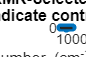


figure('Name', 'LDA Coefficient Spectrum for Selected Features', 'Position', [100, 100, 900, 600]);
% Use data directly from the potentially sorted table for consistency if needed,
% or use the original selectedWavenumbers and ldaCoefficients arrays which are ordered by feature index.
% For plotting a spectrum, it's best to sort by wavenumber.
[plot_wavenumbers_from_table, sortIdxWn_plot] = sort(featureImportanceTable.BinnedWavenumber_cm_neg1);
plot_coeffs_from_table = featureImportanceTable.LDACoefficient(sortIdxWn_plot);

stem(plot_wavenumbers_from_table, plot_coeffs_from_table, 'filled', 'MarkerSize', 4);
hold on;
plot(plot_wavenumbers_from_table, zeros(size(plot_wavenumbers_from_table)), 'k--'); % Zero line
hold off;

xlabel(sprintf('Binned Wavenumber (cm^{-1}) - Binning Factor %d', finalModelPackage.binningFactor));
ylabel('LDA Coefficient Value');
title({'LDA Coefficients for MRMR-Selected Features (WHO-1 vs WHO-3)', ...
       'Positive values indicate contribution towards WHO-3'});
grid on;
ax = gca;
ax.XDir = 'reverse'; 
if ~isempty(plot_wavenumbers_from_table)
    xlim([min(plot_wavenumbers_from_table)-mean(diff(plot_wavenumbers_from_table))/2 max(plot_wavenumbers_from_table)+mean(diff(plot_wavenumbers_from_table))/2 ]);
else
    xlim([900 1800]); 
end

ldaCoeffPlotFilenameBase = fullfile(figuresPath, sprintf('%s_Phase4_LDACoeffSpectrum_WithPvalsContext', dateStr)); % Updated name
savefig(gcf, [ldaCoeffPlotFilenameBase, '.fig']);
exportgraphics(gcf, [ldaCoeffPlotFilenameBase, '.tiff'], 'Resolution', 300);

fprintf('LDA coefficient spectrum plot saved to: %s.(fig/tiff)\n', ldaCoeffPlotFilenameBase);

LDA coefficient spectrum plot saved to: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\figures\Phase4\20250516_Phase4_LDACoeffSpectrum_WithPvalsContext.(fig/tiff)


%% 4. Plot Mean Spectra with Highlighted Important Regions
% =========================================================================
fprintf('\n--- Generating Mean Spectra Plot with Highlighted Key Features ---\n');


--- Generating Mean Spectra Plot with Highlighted Key Features ---


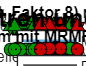

Mean spectra plot with highlighted features saved to: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\figures\Phase4\20250516_Phase4_MeanSpectra_Highlighted.(fig/tiff)



% --- 4.1. Load necessary data if not already in workspace ---
% We need X_train_full, y_train_full from the original training data file
% and wavenumbers_original
trainingDataFile = fullfile(dataPath, 'training_set_no_outliers_T2Q.mat'); % Ensure this is correct
try
    loadedTrainingData = load(trainingDataFile, 'X_train_no_outliers', 'y_train_numeric_no_outliers');
    X_train_for_mean_spectra = loadedTrainingData.X_train_no_outliers;
    y_train_for_mean_spectra = loadedTrainingData.y_train_numeric_no_outliers;
    
    % wavenumbers_original should have been loaded in Section 1 with finalModelPackage
    % If not, load it:
    if ~exist('wavenumbers_original', 'var')
        wavenumbers_data_plot = load(fullfile(dataPath, 'wavenumbers.mat'), 'wavenumbers_roi');
        wavenumbers_original_plot = wavenumbers_data_plot.wavenumbers_roi;
    else
        wavenumbers_original_plot = wavenumbers_original; % Use already loaded one
    end

catch ME
    fprintf('ERROR loading training data for mean spectra plot: %s\n', ME.message);
    % Skip this plot if data can't be loaded
    X_train_for_mean_spectra = []; 
end

if ~isempty(X_train_for_mean_spectra)
    % --- 4.2. Apply the SAME binning as used for the final model ---
    binningFactorForPlot = finalModelPackage.binningFactor;
    if binningFactorForPlot > 1
        [X_train_binned_for_plot, wavenumbers_binned_for_plot] = ...
            bin_spectra(X_train_for_mean_spectra, wavenumbers_original_plot, binningFactorForPlot);
    else
        X_train_binned_for_plot = X_train_for_mean_spectra;
        wavenumbers_binned_for_plot = wavenumbers_original_plot;
    end

    % --- 4.3. Calculate Mean Spectra for WHO-1 and WHO-3 ---
    mean_spectrum_who1_binned = mean(X_train_binned_for_plot(y_train_for_mean_spectra==1, :), 1);
    mean_spectrum_who3_binned = mean(X_train_binned_for_plot(y_train_for_mean_spectra==3, :), 1);
    difference_spectrum_binned = mean_spectrum_who3_binned - mean_spectrum_who1_binned;

    % --- 4.4. Create the Plot ---
    figure('Name', 'Mean Spectra & Difference with Highlighted MRMR-LDA Features', 'Position', [100, 100, 900, 700]);
    
    % Colors (consistent with your project prompt)
    colorWHO1 = [0.9, 0.6, 0.4]; % Orange
    colorWHO3 = [0.4, 0.702, 0.902]; % Blue
    colorDiff = [0.3 0.3 0.3]; % Grey for difference spectrum
    colorMarkerIncreaseWHO3 = [0.8 0 0]; % Red for features increasing WHO3 likelihood
    colorMarkerDecreaseWHO3 = [0 0.6 0]; % Green for features decreasing WHO3 likelihood (increasing WHO1)

    % Subplot 1: Mean Spectra with Highlighted Features
    subplot(2,1,1);
    plot(wavenumbers_binned_for_plot, mean_spectrum_who1_binned, 'Color', colorWHO1, 'LineWidth', 1.5, 'DisplayName', 'Mittelwert WHO-1');
    hold on;
    plot(wavenumbers_binned_for_plot, mean_spectrum_who3_binned, 'Color', colorWHO3, 'LineWidth', 1.5, 'DisplayName', 'Mittelwert WHO-3');
    
    % Highlight the selectedWavenumbers from finalModelPackage
    % These selectedWavenumbers are already the binned values
    selectedWnsFromModel = finalModelPackage.selectedWavenumbers;
    ldaCoeffsFromModel = ldaCoefficients; % Assuming ldaCoefficients is from Section 2 of this script

    for k_idx = 1:length(selectedWnsFromModel)
        current_selected_wn = selectedWnsFromModel(k_idx);
        % Find the index of this selected wavenumber in our full binned wavenumber axis
        % This direct comparison should work if selectedWavenumbers are a subset of wavenumbers_binned_for_plot
        plot_idx = find(abs(wavenumbers_binned_for_plot - current_selected_wn) < 1e-3, 1); % Find close match
        
        if ~isempty(plot_idx)
            marker_y_pos_who3 = mean_spectrum_who3_binned(plot_idx);
            marker_y_pos_who1 = mean_spectrum_who1_binned(plot_idx);
            
            % Determine marker color based on LDA coefficient sign
            marker_color = [0.5 0.5 0.5]; % Default grey
            if ldaCoeffsFromModel(k_idx) > 0 % Higher for WHO-3
                marker_color = colorMarkerIncreaseWHO3;
            elseif ldaCoeffsFromModel(k_idx) < 0 % Lower for WHO-3 (Higher for WHO-1)
                marker_color = colorMarkerDecreaseWHO3;
            end
            
            plot(wavenumbers_binned_for_plot(plot_idx), marker_y_pos_who3, 'v', ...
                'MarkerFaceColor', marker_color, 'MarkerEdgeColor', 'k', ...
                'MarkerSize', 7, 'HandleVisibility', 'off');
            plot(wavenumbers_binned_for_plot(plot_idx), marker_y_pos_who1, '^', ...
                'MarkerFaceColor', marker_color, 'MarkerEdgeColor', 'k', ...
                'MarkerSize', 7, 'HandleVisibility', 'off');
        end
    end
    
    hold off;
    title(sprintf('Mittlere Spektren (Gebinnt, Faktor %d) mit MRMR-LDA Merkmalen', binningFactorForPlot));
    xlabel('Wellenzahl (cm^{-1})');
    ylabel('Mittlere Absorption (A.U.)');
    ax1 = gca; ax1.XDir = 'reverse'; 
    legend('show', 'Location','NorthWest'); grid on;
    if ~isempty(wavenumbers_binned_for_plot)
        xlim([min(wavenumbers_binned_for_plot) max(wavenumbers_binned_for_plot)]);
    end

    % Create dummy plots for custom legend entries for markers
    hold on; % Add to current axes for legend purposes
    h_inc = plot(NaN,NaN,'v', 'MarkerFaceColor', colorMarkerIncreaseWHO3, 'MarkerEdgeColor','k', 'MarkerSize',7, 'DisplayName', 'Merkmal ↑ WHO-3');
    h_dec = plot(NaN,NaN,'^', 'MarkerFaceColor', colorMarkerDecreaseWHO3, 'MarkerEdgeColor','k', 'MarkerSize',7, 'DisplayName', 'Merkmal ↓ WHO-3');
    hold off;
    % Append to existing legend if possible, or create a new one if subplot changes context
    % For simplicity, this adds to the current legend. You might need to manage handles if you make it more complex.
    legend([ax1.Children(end-1:-1:end-2); h_inc; h_dec], 'Location','NorthWest'); % Rebuild legend
    
    % Subplot 2: Difference Spectrum with Highlighted Features
    subplot(2,1,2);
    plot(wavenumbers_binned_for_plot, difference_spectrum_binned, 'Color', colorDiff, 'LineWidth', 1.5, 'DisplayName', 'Differenz (WHO-3 minus WHO-1)');
    hold on;
    
    for k_idx = 1:length(selectedWnsFromModel)
        current_selected_wn = selectedWnsFromModel(k_idx);
        plot_idx = find(abs(wavenumbers_binned_for_plot - current_selected_wn) < 1e-3, 1);
        
        if ~isempty(plot_idx)
            marker_y_pos_diff = difference_spectrum_binned(plot_idx);
            marker_color = [0.5 0.5 0.5];
            if ldaCoeffsFromModel(k_idx) > 0, marker_color = colorMarkerIncreaseWHO3;
            elseif ldaCoeffsFromModel(k_idx) < 0, marker_color = colorMarkerDecreaseWHO3; end
            
            plot(wavenumbers_binned_for_plot(plot_idx), marker_y_pos_diff, 'o', ...
                'MarkerFaceColor', marker_color, 'MarkerEdgeColor', 'k', ...
                'MarkerSize', 7, 'HandleVisibility', 'off');
        end
    end
    plot(wavenumbers_binned_for_plot, zeros(size(wavenumbers_binned_for_plot)), 'k:', 'HandleVisibility','off'); % Zero line
    hold off;
    title('Differenzspektrum mit MRMR-LDA Merkmalen');
    xlabel('Wellenzahl (cm^{-1})');
    ylabel('Differenz der Absorption');
    ax2 = gca; ax2.XDir = 'reverse'; 
    legend('show', 'Location','SouthWest'); grid on;
     if ~isempty(wavenumbers_binned_for_plot)
        xlim([min(wavenumbers_binned_for_plot) max(wavenumbers_binned_for_plot)]);
    end   
    
    % Adjust layout
    sgtitle('Vergleich der mittleren Spektren und hervorgehobene Merkmale', 'FontSize', 14, 'FontWeight', 'bold');

    % Save the figure
    meanSpectraPlotFilenameBase = fullfile(figuresPath, sprintf('%s_Phase4_MeanSpectra_Highlighted', dateStr));
    savefig(gcf, [meanSpectraPlotFilenameBase, '.fig']);
    exportgraphics(gcf, [meanSpectraPlotFilenameBase, '.tiff'], 'Resolution', 300);
    fprintf('Mean spectra plot with highlighted features saved to: %s.(fig/tiff)\n', meanSpectraPlotFilenameBase);
else
    fprintf('Skipping mean spectra plot due to missing training data for plotting.\n');
end